clear; clear path; clc;
% cd('~/git/hardDiskControl/discreteTimeControl/')
load('../data/plantTF.mat');
addpath ../funcs/;
format shortG

add time delay to plant

riseTime = 0.022295; %seconds
Ts = riseTime/10;

Pz = c2d(Ps,Ts);
delay = tf(1,[1 0], Ts);
Pzd = Pz*delay;

P = 1100;
I = 1200;
D = 40;
N = 120;
Cs = pidGen(P,I,D,N,1);
Cz = c2d(Cs,riseTime/10);

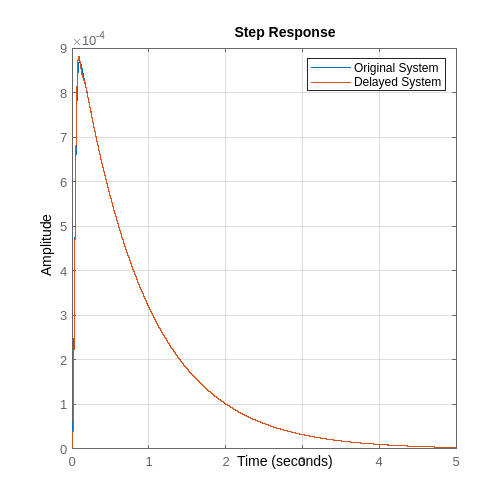

figure('Position',[0 0 1000 1000]);clf; hold on;
step(Pz/(1+Pz*Cz)); grid on;
step(Pzd/(1+Pzd*Cz)); grid on;
legend("Original System", "Delayed System")